## Problema 1

Pornim de la functiile initiale

format long
epsi = 1e-8; % precision
x = @(t) (1 - cos(t)) * cos(t);
y = @(t) (1 - cos(t)) * sin(t);

Calculam valoarea exacta folosind int in MATLAB

syms a
ve = int((sin(a) .* sin(a) + cos(a) .* (1 - cos(a))).^2 + (sin(2.*a) - sin(a)).^2, [0, 2*pi]);
vep = double(vpa(ve)) % valoarea integralei

vep =   12.566370614359172


Calculam formula functiei cu derivatele lor

F = @(t) (sin(t) .* sin(t) + cos(t) .* (1 - cos(t))).^2 + (sin(2.*t) - sin(t)).^2;

Vizualizam graficul functiei

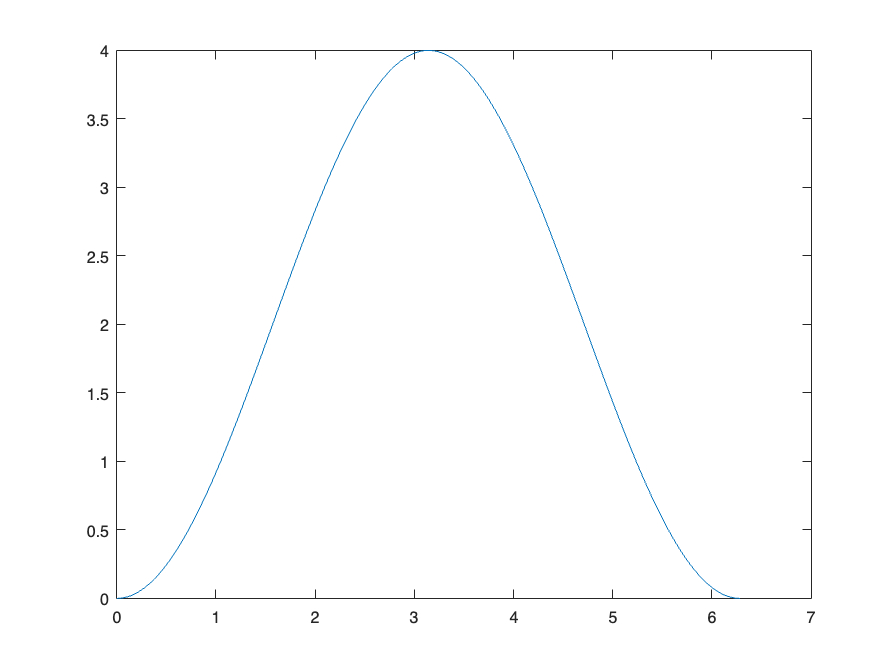

points = linspace(0, 2 * pi, 300);
plot(points, F(points));

### Romberg

[R, iter] = Romberg(F, 0, 2 * pi, epsi)

R =   12.566370614359171


iter =    129


abs(R - vep)

ans =      1.776356839400250e-15


Putem observa ca precizia in cazul folosirii metodei lui Romberg este foarte buna

### Cuadratura adaptiva

[Q, iter] = AdQuad(F, 0, 2 * pi, epsi)

Q =   12.566370614359172


iter =      9


abs(Q - vep)

ans =      0


Folosind o cuadratura adaptiva rezultatul este mult mai precis si converge mult mai rapid

## Problema obligatorie

clear
syms x f(x) a b

**Pentru a elimina cat mai mult eroarea umana si a imbunatatii calitatea pe parcursul rezolvarii acestor cerinte au fost dezvoltate niste solutii simbolice**

### a)

R = RombergSym(f, a, b, 10); % calculam matricea aferenta Romberg

Romberg elementul $R_{2,2}$

disp(prod(factor(simplify(R(2,2)))))

$$-\frac{\left(-b+a\right)\,\left(4\,f\left(\frac{b}{2}+\frac{a}{2}\right)+f\left(a\right)+f\left(b\right)\right)}{6}$$

Simpson

SimpsonSym(f, a, b, 2)

$$ans = -\left(-\frac{b}{6}+\frac{a}{6}\right)\,\left(4\,f\left(\frac{b}{2}+\frac{a}{2}\right)+f\left(a\right)+f\left(b\right)\right)$$

Romberg elementul $R_{3,2}$

disp(prod(factor(simplify(R(3,2)))))

$$-\frac{\left(-b+a\right)\,\left(2\,f\left(\frac{b}{2}+\frac{a}{2}\right)+4\,f\left(\frac{3\,b}{4}+\frac{a}{4}\right)+4\,f\left(\frac{b}{4}+\frac{3\,a}{4}\right)+f\left(a\right)+f\left(b\right)\right)}{12}$$

SimpsonSym(f, a, b, 4)

$$ans = -\left(-\frac{b}{12}+\frac{a}{12}\right)\,\left(2\,f\left(\frac{b}{2}+\frac{a}{2}\right)+4\,f\left(\frac{3\,b}{4}+\frac{a}{4}\right)+4\,f\left(\frac{b}{4}+\frac{3\,a}{4}\right)+f\left(a\right)+f\left(b\right)\right)$$

Se poate observa ca avem primii doi termeni identici in cadrul celor doua, prin inductie matematica se poate demonstra ipoteza 

### b)

Romberg elementul $R_{3,3}$

disp(prod(factor(simplify(R(3,3)))))

$$-\frac{\left(-b+a\right)\,\left(12\,f\left(\frac{b}{2}+\frac{a}{2}\right)+32\,f\left(\frac{3\,b}{4}+\frac{a}{4}\right)+32\,f\left(\frac{b}{4}+\frac{3\,a}{4}\right)+7\,f\left(a\right)+7\,f\left(b\right)\right)}{90}$$

BooleVillarceauSym(f, a, b, 1)

$$ans = -\frac{2\,\left(-\frac{b}{4}+\frac{a}{4}\right)\,\left(12\,f\left(\frac{b}{2}+\frac{a}{2}\right)+32\,f\left(\frac{3\,b}{4}+\frac{a}{4}\right)+32\,f\left(\frac{b}{4}+\frac{3\,a}{4}\right)+7\,f\left(a\right)+7\,f\left(b\right)\right)}{45}$$

Romberg elementul $R_{4,3}$

disp(prod(factor(simplify(R(4,3)))))

$$-\frac{\left(-b+a\right)\,\left(14\,f\left(\frac{b}{2}+\frac{a}{2}\right)+12\,f\left(\frac{3\,b}{4}+\frac{a}{4}\right)+12\,f\left(\frac{b}{4}+\frac{3\,a}{4}\right)+32\,f\left(\frac{7\,b}{8}+\frac{a}{8}\right)+32\,f\left(\frac{5\,b}{8}+\frac{3\,a}{8}\right)+32\,f\left(\frac{3\,b}{8}+\frac{5\,a}{8}\right)+32\,f\left(\frac{b}{8}+\frac{7\,a}{8}\right)+7\,f\left(a\right)+7\,f\left(b\right)\right)}{180}$$

BooleVillarceauSym(f, a, b, 2)

$$ans = -\frac{2\,\left(-\frac{b}{8}+\frac{a}{8}\right)\,\left(14\,f\left(\frac{b}{2}+\frac{a}{2}\right)+12\,f\left(\frac{3\,b}{4}+\frac{a}{4}\right)+12\,f\left(\frac{b}{4}+\frac{3\,a}{4}\right)+32\,f\left(\frac{7\,b}{8}+\frac{a}{8}\right)+32\,f\left(\frac{5\,b}{8}+\frac{3\,a}{8}\right)+32\,f\left(\frac{3\,b}{8}+\frac{5\,a}{8}\right)+32\,f\left(\frac{b}{8}+\frac{7\,a}{8}\right)+7\,f\left(a\right)+7\,f\left(b\right)\right)}{45}$$

Din nou avem doi termeni care corspund regulii, pe baza aceasta putem demonstra prin inductie, ipoteza

### c) verificare

#### a)

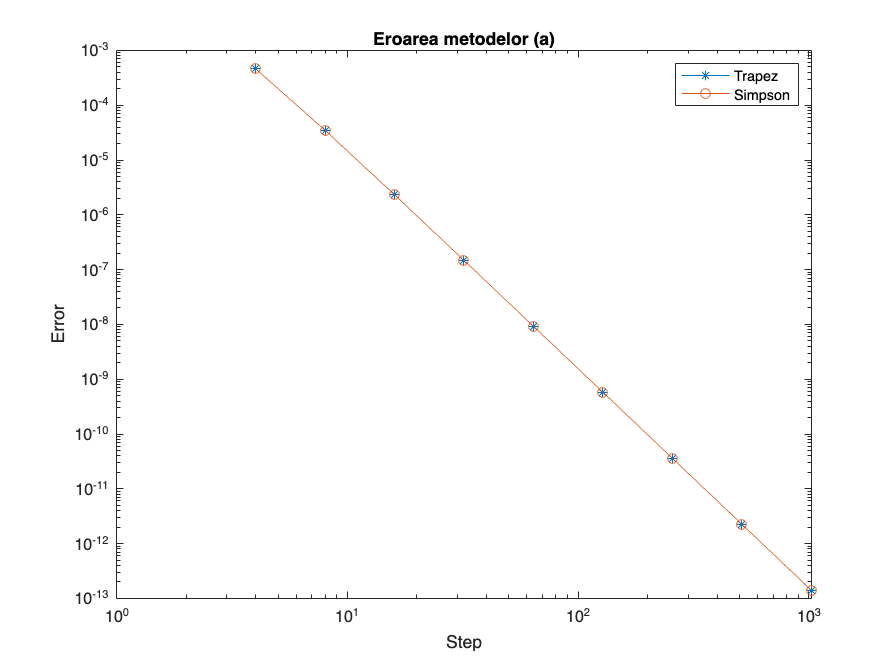

clear
f = @(x) log(x);
a = 1;
b = 2;
integral = 2 * log(2) - 1;

n = 10;
steps = 2 .^ (1:n);

errors_trap = zeros(n, 1);
errors_simp = zeros(n, 1);
R = RombergSym(f, a, b, n);

for i = 2:n
    nodes_simpson = steps(i-1);
    I_Romberg = R(i, 2);
    I_Simson = SimpsonSym(f, a, b, nodes_simpson);

    errors_trap(i) = abs(I_Romberg - integral);
    errors_simp(i) = abs(I_Simson - integral);
end

loglog(steps, errors_trap, '-*', steps, errors_simp, '-o');
xlabel('Step');
ylabel('Error');
legend('Trapez', 'Simpson');
title('Eroarea metodelor (a)');

#### b)

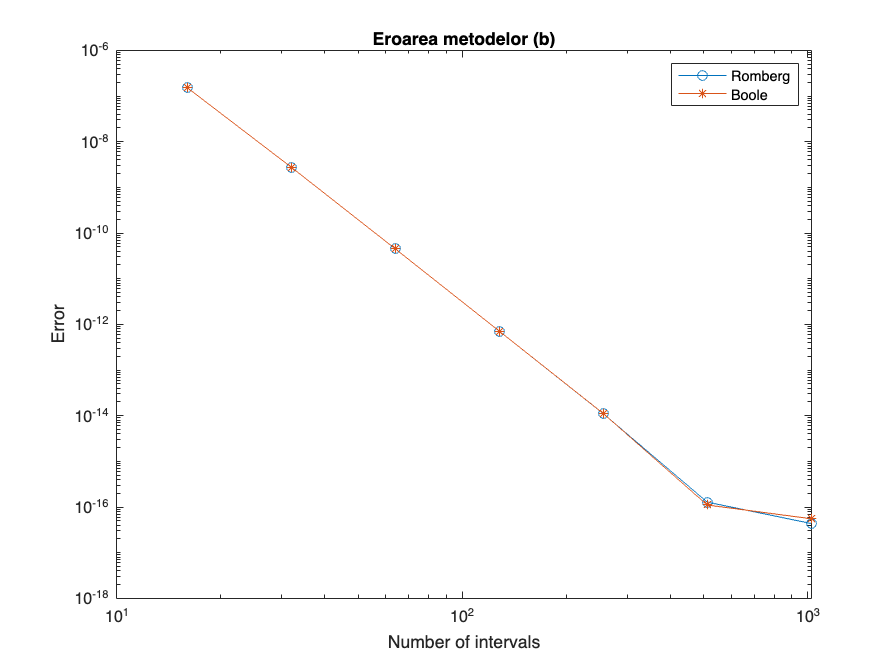

f = @(x) log(x);
a = 1;
b = 2;
integral = 2 * log(2) - 1;

n = 10;

steps = 2 .^ (1:n);  

errors_romberg = zeros(n,1); 
errors_boole = zeros(n,1);
R = RombergSym(f, a, b, n);

for i = 4:n
    nodes_boole = steps(i - 3);  

    I_Romberg = R(i, 3);
    I_Boole = BooleVillarceauSym(f, a, b, nodes_boole);

    errors_romberg(i) = abs(I_Romberg - integral);
    errors_boole(i) = abs(I_Boole - integral);
end

loglog(steps, errors_romberg, '-o', steps, errors_boole, '-*');
xlabel('Number of intervals');
ylabel('Error');
legend('Romberg', 'Boole');
title('Eroarea metodelor (b)');